# Actividad 4.1 (Evaluación)

- **Implementar** el código requerido para generar las siguientes trayectorias a partir de las velocidades angulares y lineales en un plano 2D.

clear
close all
clc

Primero definimos los puntos donde se calcularán las posiciones x(t)x(t)x(t) y y(t)y(t)y(t).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 30;             % Tiempo de simulacion en segundos (s)
ts = 0.7;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posici�n en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posici�n en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) =0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

Funciones parametrizadas en términos de θ, que a su vez está mapeado con el tiempo. En este caso como queremos realizar una trayectoria circular vamos de 0 a 2 pi, y el radio tiene que ser de 4 de acuerdo a la función dada. Parametrizamos la función  en función del ángulo θ para poder generar puntos de manera continua y suave:

**F(x) =** **x^2** **+** **y****^2** **-16**

% Crear la trayectoria del semicírculo superior
% Crear la trayectoria de una circunferencia completa
theta = linspace(0, 2*pi, N+1);  % Ángulo de 0 a 2pi
radius = 4;                      % Radio de la circunferencia

x_traj = radius * cos(theta);   % Coordenada x
y_traj = radius * sin(theta);   % Coordenada y


Calculamos la orientación a donde esta apuntando el robot

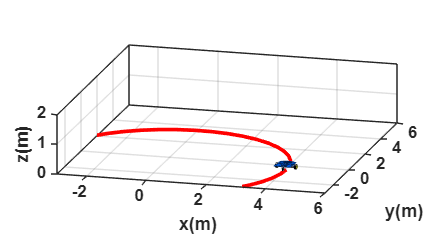

% Derivar orientación a partir de la trayectoria
phi = zeros(1, N+1);
for k = 1:N
    dx = x_traj(k+1) - x_traj(k);
    dy = y_traj(k+1) - y_traj(k);
    phi(k) = atan2(dy, dx);
end
phi(end) = phi(end-1); % Mantener la última orientación

% Asignar la trayectoria al robot
x1 = x_traj;
y1 = y_traj;
hx = x_traj;
hy = y_traj;

% Calcular velocidades lineales y angulares
u = zeros(1,N);
w = zeros(1,N);
for k = 1:N
    dx = x1(k+1) - x1(k);
    dy = y1(k+1) - y1(k);
    u(k) = sqrt(dx^2 + dy^2) / ts; % velocidad lineal
    dphi = phi(k+1) - phi(k);
    w(k) = dphi / ts;              % velocidad angular
end


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    phi(k+1) = phi(k) + w(k) * ts; 
    xp1 = u(k) * cos(phi(k+1)); 
    yp1 = u(k) * sin(phi(k+1));
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-3 6 -3 6 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 1;
for k=1:step:N
    delete(H1);    
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

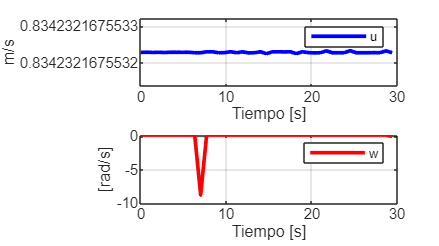


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph, 'position', sizeScreen);
subplot(211)
plot(t, u, 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('m/s'), legend('u');
subplot(212)
plot(t, w, 'r', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w');

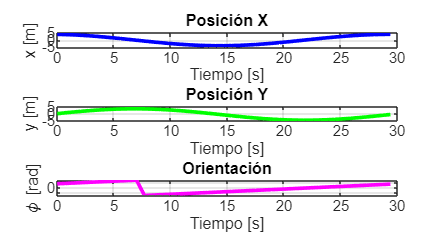


%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES ANGULARES DE LAS RUEDAS %%%%%%%%%%%%%%%%%%%

r = 0.05; % Radio de las ruedas en metros
L = 0.3;  % Distancia entre ruedas (track width) en metros

wl = zeros(1, N);
wr = zeros(1, N);

for k = 1:N
    wl(k) = (2*u(k) - w(k)*L)/(2*r);
    wr(k) = (2*u(k) + w(k)*L)/(2*r);
end

%%%%%%%%%%%%%%%%%%% GRAFICAR POSE Y VELOCIDADES ANGULARES %%%%%%%%%%%%%%%%%%%

pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t, x1(1:N), 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('x [m]'), title('Posición X');

subplot(312)
plot(t, y1(1:N), 'g', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('y [m]'), title('Posición Y');

subplot(313)
plot(t, phi(1:N), 'm', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('\phi [rad]'), title('Orientación');

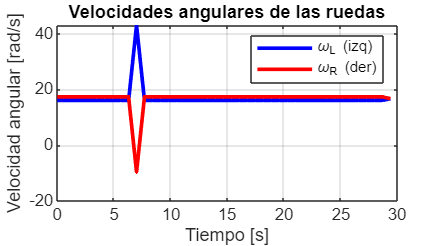


wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);
plot(t, wl, 'b', 'LineWidth', 2), hold on
plot(t, wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')







%%%%%%%%%%%%%%%%%%Trayectoria 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Aumentamos el número de los puntos donde se calcularán las posiciones x(t) y y(t) ya que necesitaremos más precisión en esta trayectoria pues es más compleja


tf = 60;             % Tiempo de simulacion en segundos (s)
ts = 0.05;           % Tiempo de muestreo en segundos (s)
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%%%%%% TRAJECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%

Muestramos la trayectoria, elegimos muchos valores de x uniformemente espaciados, y luego calculamos el valor correspondiente de y.

Obteniendo una tabla de pares (xi�,yi�) que representan puntos de la trayectoria deseada.

% Trayectoria deseada: y = 2*sin(x^2), con x entre 0 y 5
x_traj = linspace(0, 5, N);
y_traj = 2 * sin(x_traj.^2);

 Usamos interpolación con splines para transformar esos puntos discretos en una función continua y suave de tiempo .

% Crear splines suaves de x(t) y y(t)
x_spline = spline(t, x_traj);
y_spline = spline(t, y_traj);

Como tenemos x(t) y y(t)como splines, derivamos esos splines usando `fnder`, que devuelve otro spline que representa la derivada. Luego usamos `ppval` para evaluar esas derivadas en cada instante del tiempo. Así conseguimos las derivadas de forma suave y precisa.

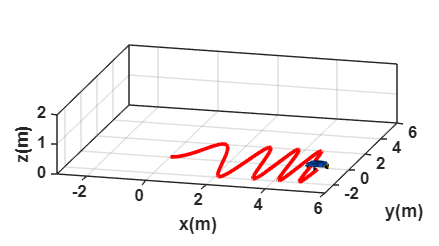

% Derivar suavemente la orientación
dx = ppval(fnder(x_spline), t);
dy = ppval(fnder(y_spline), t);
phi_ref = atan2(dy, dx);

% Inicializar vectores de estado
x1 = zeros(1, N);
y1 = zeros(1, N);
phi = zeros(1, N);

x1(1) = x_traj(1);
y1(1) = y_traj(1);
phi(1) = phi_ref(1);

% Inicializar punto de control (para graficar la trayectoria seguida)
hx = zeros(1, N);
hy = zeros(1, N);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1, N-1);  % Velocidad lineal
w = zeros(1, N-1);  % Velocidad angular

for k = 1:N-1
    dx = x_traj(k+1) - x_traj(k);
    dy = y_traj(k+1) - y_traj(k);
    u(k) = sqrt(dx^2 + dy^2) / ts;
    dphi = phi_ref(k+1) - phi_ref(k);
    w(k) = dphi / ts;
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N-1
    xp1 = u(k) * cos(phi(k));
    yp1 = u(k) * sin(phi(k));
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;
    phi(k+1) = phi_ref(k+1);
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-3 6 -3 6 0 2]);  % Ajustar límites del entorno

% Incluir archivos de visualización de robot
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 1;
for k = 1:step:N
    delete(H1);    
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1, k), 'r', 'lineWidth', 2);
    pause(ts);
end

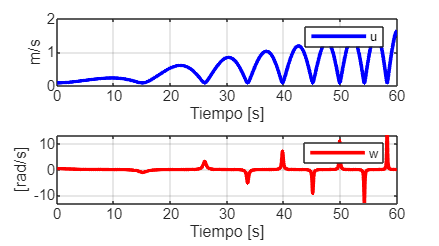



%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
t_ref = t(1:N-1);  % Nuevo tiempo de referencia para u y w
graph = figure;
set(graph, 'position', sizeScreen);
subplot(211)
plot(t_ref, u, 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('m/s'), legend('u');
subplot(212)
plot(t_ref, w, 'r', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w');

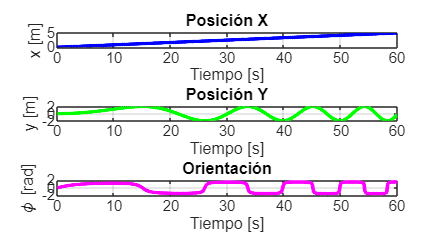



%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES ANGULARES DE LAS RUEDAS %%%%%%%%%%%%%%%%%%%

r = 0.05; % Radio de las ruedas en metros
L = 0.3;  % Distancia entre ruedas (track width) en metros

wl = zeros(1, N-1);
wr = zeros(1, N-1);

for k = 1:N-1
    wl(k) = (2*u(k) - w(k)*L)/(2*r);
    wr(k) = (2*u(k) + w(k)*L)/(2*r);
end

%%%%%%%%%%%%%%%%%%% GRAFICAR POSE Y VELOCIDADES ANGULARES %%%%%%%%%%%%%%%%%%%

pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t, x1(1:N), 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('x [m]'), title('Posición X');

subplot(312)
plot(t, y1(1:N), 'g', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('y [m]'), title('Posición Y');

subplot(313)
plot(t, phi(1:N), 'm', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('\phi [rad]'), title('Orientación');

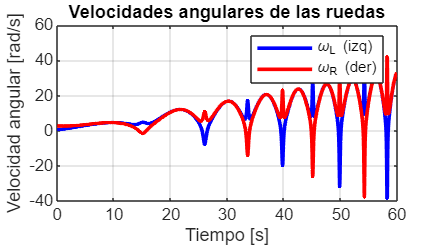


wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);
plot(t_ref, wl, 'b', 'LineWidth', 2), hold on
plot(t_ref, wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')




%%%%%%%%%%%%%%%Trayectoria 3 %%%%%%%%%%%%%%%%%%%%%

clear

clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 40;             
ts = 0.1;            
t = 0: ts: tf;       
N = length(t);       

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1 = zeros (1,N+1);  
y1 = zeros (1,N+1);  
phi = zeros(1, N+1); 

x1(1) = 0;    
y1(1) = 0;   
phi(1) = 0;  

hx = zeros(1, N+1);  
hy = zeros(1, N+1);  

hx(1) = x1(1); 
hy(1) = y1(1); 

%%%%%%%%%%%%%%%%%%%%%% NUEVA TRAYECTORIA POR TRAMOS %%%%%%%%%%%%%%%%%%%%%%%%%%

% Creamos la trayectoria con desplazamiento uniforme en x


Genero un vector de valores x que van uniformemente desde –6 hasta 6, con un total de `N+1` puntos.

x1 = linspace(-6, 6, N+1);

Este bloque recorre todos los valores de x generados anteriormente y calcula el valor de y correspondiente usando una función definida por tramos.

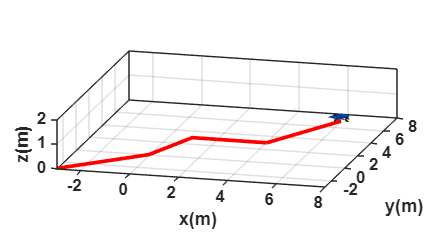

% Calcular y = f(x) por tramos
for i = 1:N+1
    x = x1(i);
    if x <= 0
        y1(i) = x;
    elseif x > 0 && x <= 1
        y1(i) = 3*x;
    elseif x > 1 && x < 4
        y1(i) = 3;
    elseif x >= 4
        y1(i) = 2*x - 5;
    end
end


% Calcular orientación phi a partir de la trayectoria
for k = 1:N
    dx = x1(k+1) - x1(k);
    dy = y1(k+1) - y1(k);
    phi(k) = atan2(dy, dx);
end
phi(end) = phi(end-1); 

hx = x1;
hy = y1;

%%%%%%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N);
w = zeros(1,N);
for k = 1:N
    dx = x1(k+1) - x1(k);
    dy = y1(k+1) - y1(k);
    u(k) = sqrt(dx^2 + dy^2) / ts;
    dphi = phi(k+1) - phi(k);
    w(k) = dphi / ts;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N
    xp1 = u(k) * cos(phi(k+1)); 
    yp1 = u(k) * sin(phi(k+1));
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% VISUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-3 8 -3 8 0 2]); 

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 1;
for k = 1:step:N
    delete(H1);    
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

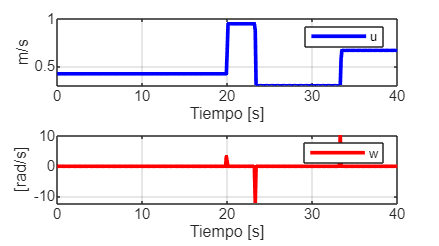


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas u y w %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph, 'position', sizeScreen);
subplot(211)
plot(t, u, 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('m/s'), legend('u');
subplot(212)
plot(t, w, 'r', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w');

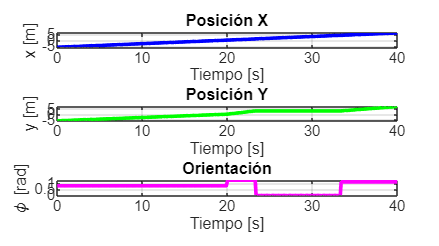


%%%%%%%%%%%%%%%%%%% VELOCIDADES ANGULARES RUEDAS %%%%%%%%%%%%%%%%%%%
r = 0.05; 
L = 0.3;  

wl = zeros(1, N);
wr = zeros(1, N);

for k = 1:N
    wl(k) = (2*u(k) - w(k)*L)/(2*r);
    wr(k) = (2*u(k) + w(k)*L)/(2*r);
end

%%%%%%%%%%%%%%%%%%% GRAFICAR POSE Y VELOCIDADES ANGULARES %%%%%%%%%%%%%%%%%%%

pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t, x1(1:N), 'b', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('x [m]'), title('Posición X');

subplot(312)
plot(t, y1(1:N), 'g', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('y [m]'), title('Posición Y');

subplot(313)
plot(t, phi(1:N), 'm', 'LineWidth', 2), grid on, xlabel('Tiempo [s]'), ylabel('\phi [rad]'), title('Orientación');

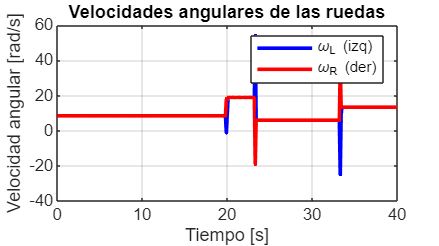


wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);
plot(t, wl, 'b', 'LineWidth', 2), hold on
plot(t, wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')